This script will comare the total power required to maintain 10V at the leaf nodes of a dendrite with various configurations. One will be a dendrite with the R value doubling at each branch, another will keep the resistance values constant for all branches, another will base it on the length of the branch (for the Trees dendrites I created these two will be the same), and another will be the ladder network with each R value set by the length of the branch.


clear

load dendrites10.mat;
Vdd = 10;


n = 16;
d1 = dendrite(trees{n}.dA, trees{n}.X, trees{n}.Y, []);
V = zeros(d1.nodes,5);
I = zeros(d1.nodes,5);
P = zeros(1,5);

lad1 = d1.ladder;


## Double at each branch

d1.setR('d',100);
count = 1;
[V(:,count,:) I(:,count)] = d1.DC(Vdd);
P(count) = max(I(count))*Vdd

P =     0.4000         0         0         0         0


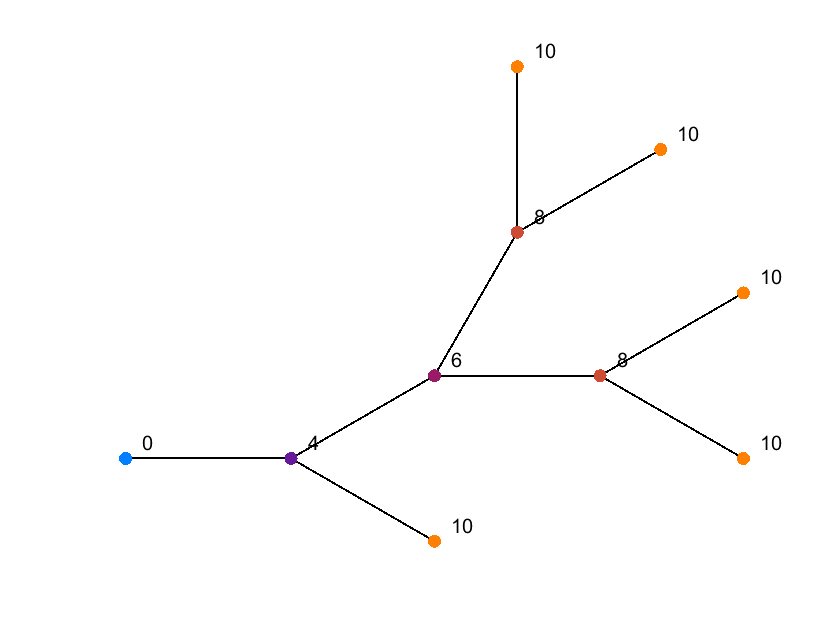

Current plot held


d1.plot(V(:,count),'o');

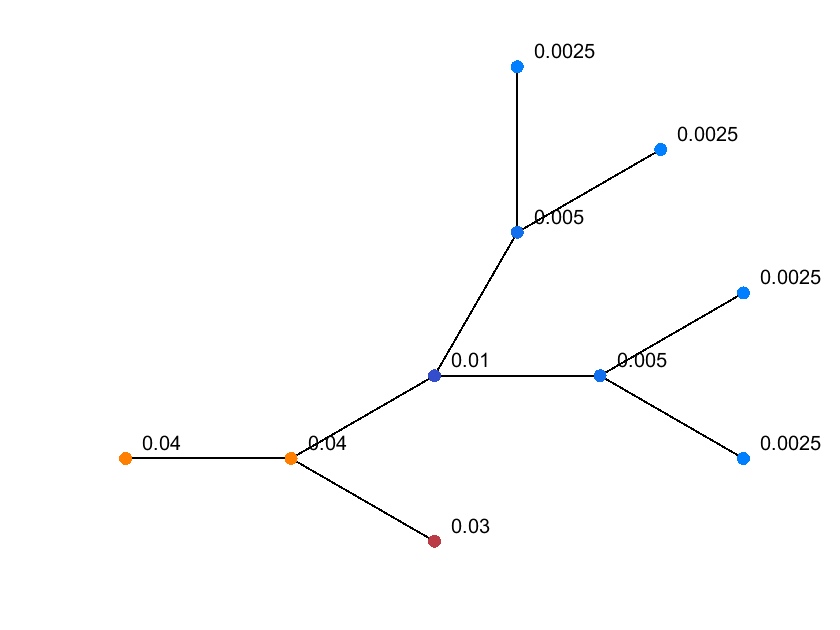

Current plot held


d1.plot(I(:,count),'o');

## Constant R (100Ω)

d1.setR('c',100);
count = count+1;
[V(:,count,:) I(:,count)] = d1.DC(Vdd);
P(count) = max(I(:,count))*Vdd

P =     0.4000    0.6111         0         0         0


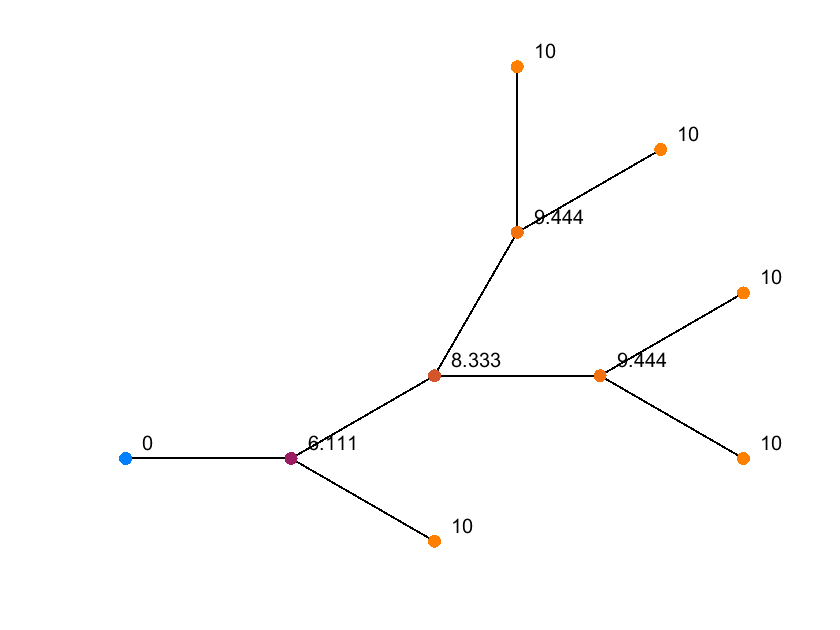

Current plot held


d1.plot(V(:,count),'o');

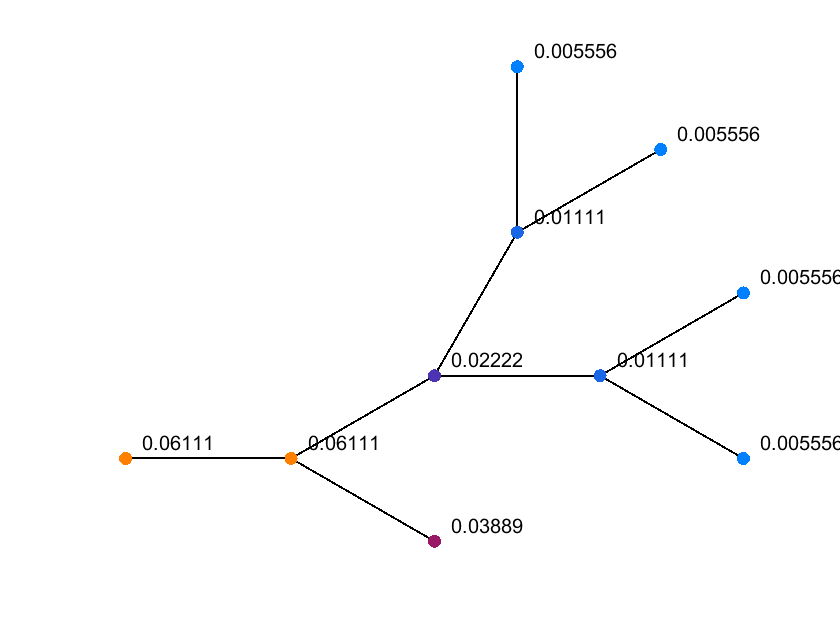

Current plot held


d1.plot(I(:,count),'o');

## Constant R (800Ω)

d1.setR('c',800);
count = count+1;
[V(:,count,:) I(:,count)] = d1.DC(Vdd);
P(count) = max(I(:,count))*Vdd

P =     0.4000    0.6111    0.0764         0         0


Current plot held


d1.plot(V(:,count),'o');

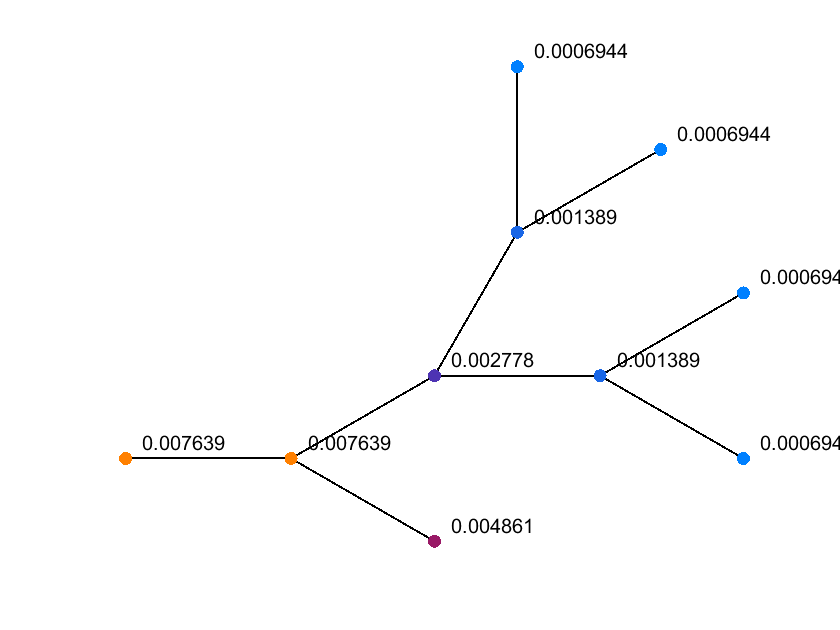

Current plot held


d1.plot(I(:,count),'o');

## Ladder (100Ω start)

count = count+1;
[Vlad, Ilad] = lad1.DC(Vdd);
P(count) = max(Ilad)*Vdd

P =     0.4000    0.6111    0.0764    0.2464         0


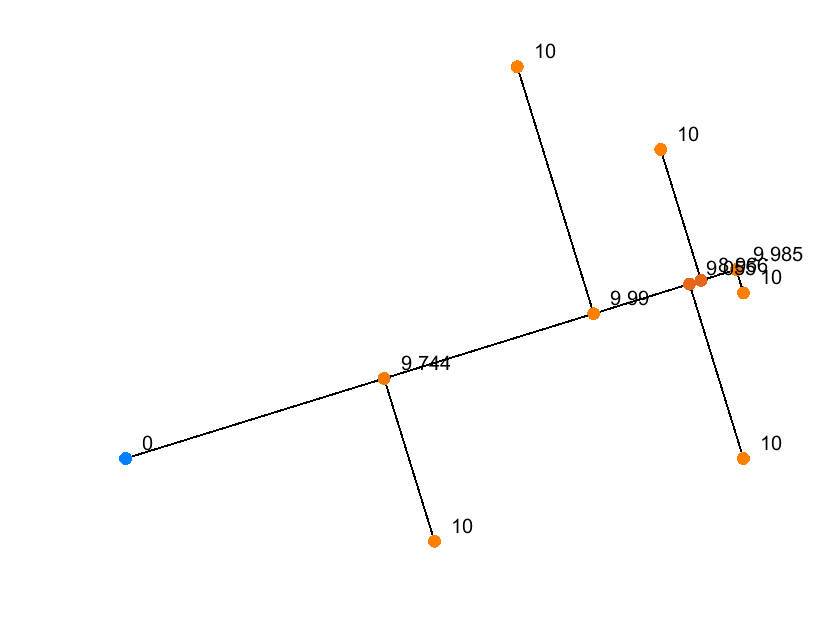

Current plot held


lad1.plot(Vlad,'o');

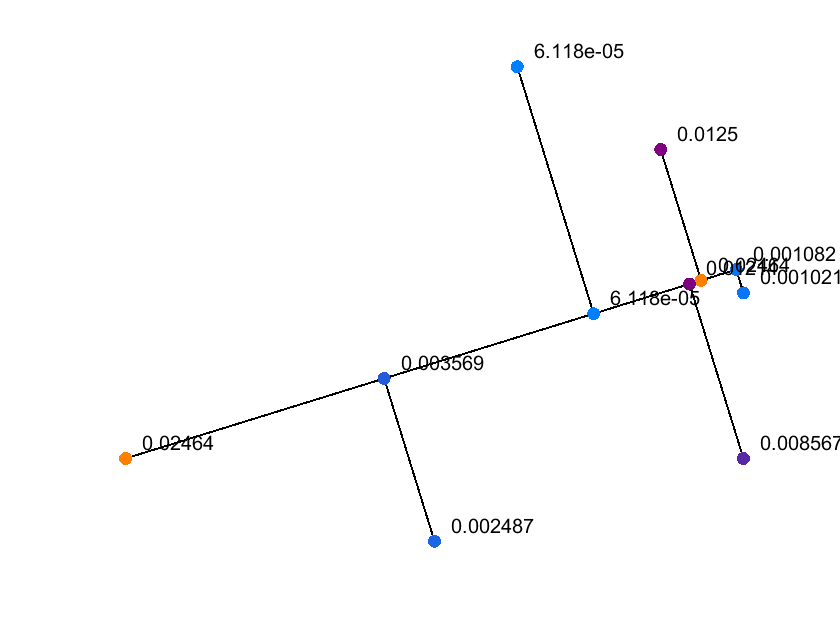

Current plot held


lad1.plot(Ilad,'o');